# Model-Based Development of Controls for a Balancing Robot

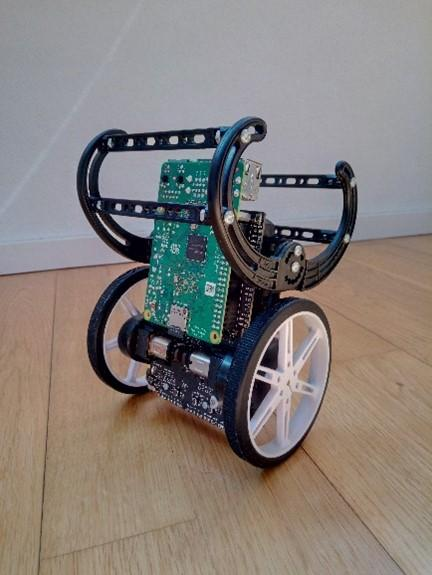

## Overview

In this project we will design the controls for a low-cost balancing robot. Throughout the project we will use the model-based design approch. This means that we make use of in-silico models of robot components such as the motors from the very beginning. The parameters of these models will be adjusted to fit the real specifications of the robot. The final model, our so-called digital twin, is then used to design the low and high-level controllers. These will be validated using simulation before deploying them to the target hardware.

## Hardware and Controls Approach

The project uses the [Balboa Robot from Pololu](https://www.pololu.com/product/3575) [1]. It consist of a custom Arduino board that carries two motors, encoders and an inertial measurement unit. The latter is for pose estimation. To make the robot more versatile it is extended with a Raspberry Pi 3B+. The general approach for our controls implementation is as follows. 

- Arduino board: Low-level control of the motors (i.e. using PID) $\rightarrow$ sample time 0.01s

- Raspberry Pi: High-level control for balancing (LQR) and position (PID) $\rightarrow$ sample time 0.01s for balancing and 0.1 for position.

- Data connection between the two boards is implemented using I2C.

Note: As a design principle the inner loop controllers should run faster than outer loop controllers. Since the motor position signal from the encoders has a low resolution, this is only partly fulfilled. PIDs for speed control and balancing control are currently running with the same sample time of 0.01s.

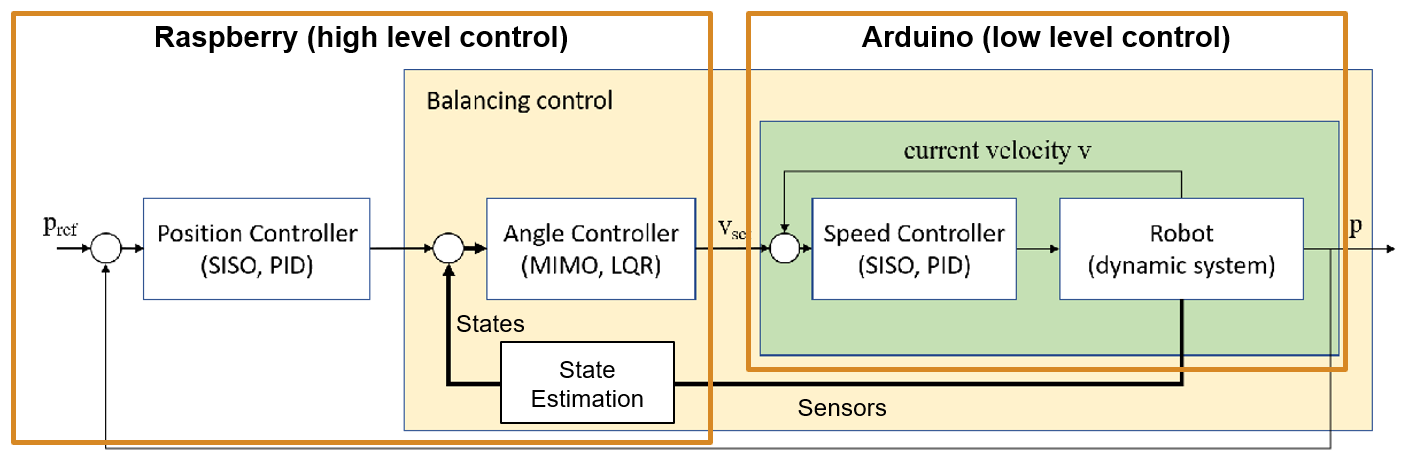

**Figure: **Picture of the overall controls architecture. The system contains several controllers that are arranged in a cascade. The position control as well as the speed control can be classified as SISO systems (single input single output). They can be conveniently implemented using a PID controller. The more advanced control task is the stabilization of the robot angle. As described in [2] this can be accomplished using an LQR regulator. The green part of the figure below is implemented on the Arduino board. All the other parts run on the Raspberry Pi.

The general approach is to build the digital twin of the robot using a bottum-up approach. Meaning we start with the motor control, then continue with the LQR controller and finish with the position controller.

## Workflow Steps

- [Low-level Motor Control using the Arduino Board](matlab:open('Ch1_Arduino_Motor_Control.mlx'))

- [Integration into a Mechanical Model](matlab:open('.\Ch2_Mechanical_Model.mlx'))

- [Balancing and Position Control](matlab:open('.\Ch3_ControllerDesign.mlx'))

- [Sensor Modeling](matlab:open('.\CH4_SensorModeling.mlx'))

- [State Estimation using Sensor Fusion](matlab:open('.\Ch5_StateEstimation.mlx'))

- [State Control using Stateflow](matlab:open('.\Ch6_StateControl.mlx'))

- [Deployment](matlab:open('.\Ch7_Deployment.mlx'))

## Recommended Prework/Prerequisites

The reader should be familiar with Simulink and Simscape. The easiest way to get acquainted with these tools is to take the following online trainings.

- Simulink Onramp (2h): [https://matlabacademy.mathworks.com/details/simulink-onramp/simulink](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink)

- Simscape Onramp (1h): [https://matlabacademy.mathworks.com/details/simscape-onramp/simscape](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape)

## Hardware Setup

### Simulink Support Package for Arduino

The following commands checks if the required Hardware Support Package is installed. 

checkHSP('Simulink Support Package for Arduino Hardware')

### Simulink Support Package for Raspberry Pi

(starting R2026a this will be a blockset)

checkHSP('Simulink Support Package for Raspberry Pi Hardware')

Simulink Support Package for Arduino Hardware is installed


**The standard setup process for the Raspberry Support Package requires an ethernet cable (might need an adapter). In case this does not work you can also install the package via Wifi. For this please follow these steps:**

- Start Raspberry and connect display, keyboard, etc.

- Connect the Raspberry to your local WiFi

- Open the network properties and get the IP address → use this in the setup wizard.

Note, if you configure the Raspberry via WiFi, you can use this connection as well to deploy code.

### Supplementary functions for setup check

function checkHSP(packageName)

Simulink Support Package for Raspberry Pi Hardware is installed



    % Get a list of installed support packages
    installedPackages = matlabshared.supportpkg.getInstalled();
    
    % Check if the specified package is installed
    isInstalled = any(strcmp({installedPackages.Name}, packageName));
    
    if isInstalled
        disp([packageName ' is installed. Please make sure that you also completed the setup process with your Raspberry Pi.']);
    else
        disp([packageName ' is not installed. Please install this SP via the Add-On Explorer and follow instructions in the Setup process.']);

    end

end

## References

[1] Pololu Inc., “Pololu Balboa 32U2 Balancing Robot User’s Guide”, Available: [https://www.pololu.com/docs/pdf/0J70/balboa_32u4_robot.pdf,](https://www.pololu.com/docs/pdf/0J70/balboa_32u4_robot.pdf,) [Accessed: Sept. 15, 2025]

[2] C.-E. Framing, R. Hedinger, E. S. Iglesias, F.-J. Heeler, and D. Abel, “EduBal: An open balancing robot platform for teaching control and system theory”, *IFAC-**PapersOnLine*, Vol. 53, no. 2, 2020.